t = 1000000./[diff(t1),diff(t2)];

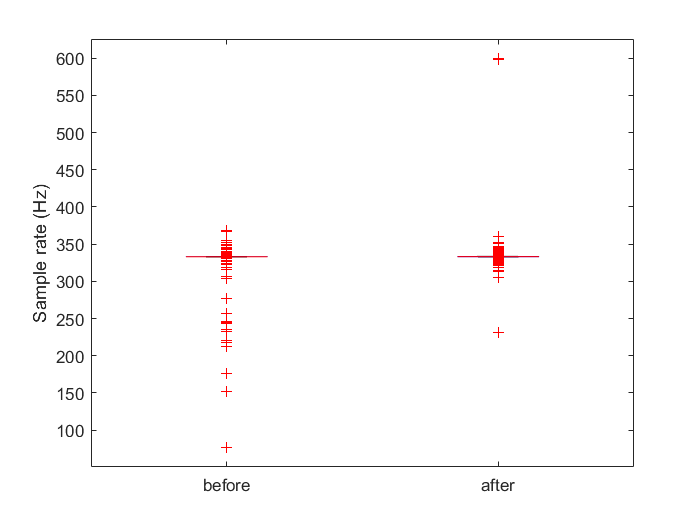

boxplot(t, 'labels', {'before', 'after'})
ylabel("Sample rate (Hz)")

std(t, 'omitnan')

ans =    15.5936   18.2833


mean(t,"omitnan")

ans =   331.9030  333.8197


t_raw = [diff(t1), diff(t2)]./1000;
boxplot(t_raw, 'labels', {'Initial Data Recording', 'Final Data Recording'})
ylabel("Time between samples (ms)")
std(t_raw, 'omitnan')

ans =     0.3733    0.1226


mean(t_raw,"omitnan")

ans =     3.0283    3.0018


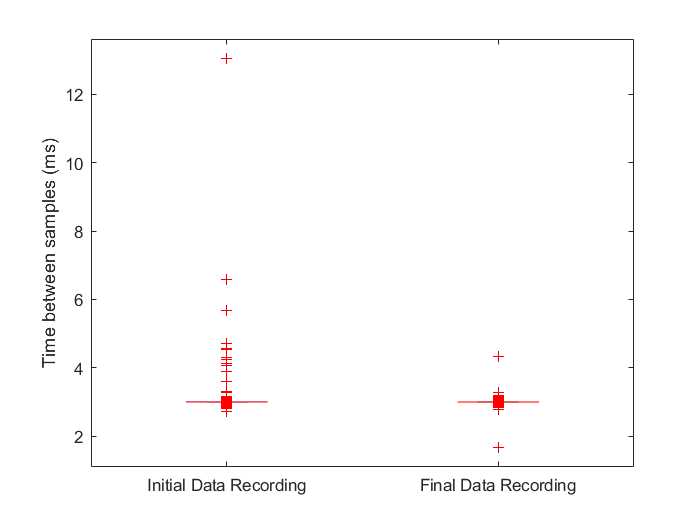

f = gcf;
exportgraphics(f,'figures/data_recording.png','Resolution',300)   

sum(t_raw(:,1) > 3.2)

ans = 16

sum(t_raw(:,2) > 3.2)

ans = 5

isout = isoutlier(t_raw,'quartiles');
tClean = t_raw;
tClean(isout) = NaN;

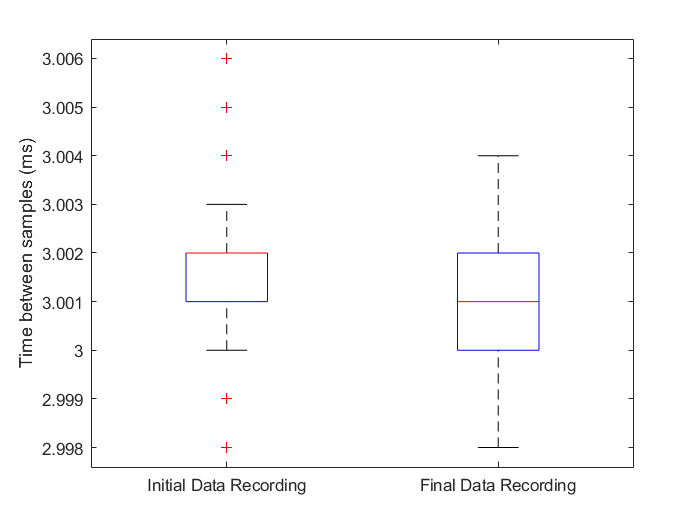

boxplot(tClean, 'labels', {'Initial Data Recording', 'Final Data Recording'})
ylabel("Time between samples (ms)")

std(t_raw, 'omitnan')

ans =     0.3733    0.1226


mean(t_raw,"omitnan")

ans =     3.0283    3.0018


f = gcf;